## **Tarea Nº1: **

# **Procesamiento y Reconstrucción de Imágenes Médicas**

#### Universidad Técnica Federico Santa Maria

#### Departamento de Informatica - CSSJ - CC

#### ENUNCIADO

**a) Interpolación Trilineal (20 pts): **La siguiente página de Wikipedia ([https://acortar.link/q9pEiw](https://acortar.link/q9pEiw)), muestra matemáticamente como se puede realizar la Interpolación Trilineal. Desarrolle su propio código en forma de función de MATLAB, que reciba como entrada una imagen 3D, y un factor de escalamiento. Por ejemplo ***“im_out = trilineal_XX_YY(im_in, factor)”***, donde: 

- **XX_YY** = iniciales del nombre y apellido de los/as integrantes del grupo. 

- **im_in** = es el volumen de entrada. 

- **factor** = factor de escalamiento que va entre 0.05 < factor < 2 para este caso. 

El factor de escalamiento quiere decir que cuando factor tenga un valor de 0.5, mi imagen de salida tendrá un 50% del tamaño original, cuando tenga un valor de 2 la imagen de salida debe tener el doble del tamaño de la imagen original.  El código debe funcionar para cualquier rango de valores entre 0.05 y 2.

Genere una sección de “Help” en su función de MATLAB, donde describa brevemente lo que hace su código y adicionalmente debe definir los inputs, outputs, y incluir un ejemplo de ejecución de su código. 

***No se pueden usar las funciones de interpolación de Matlab, debe desarrollar su propio código***.

% Código:
function im_out = trilineal_CHEHADE_CASIVAR(im_in, factor)
    % Escala una imagen 3D según el factor indicado, utilizando
    % interpolación trilineal con método secuencial.
    %
    % Inputs:
    % - im_in: Imagen 3D de entrada.
    % - factor: Factor de escalamiento para el volumen de salida. 
    %
    % Outputs:
    % - im_out: Imagen 3D escalada resultante.
    %
    % Ejemplo de uso:
    % - Sea IMG una imagen 3D.
    % IMG_escalada = trilineal_CHEHADE_CASIVAR(IMG, 1.25);
    %
    % Estrategia:
    % Primero se generó el nuevo volumen del tamaño correspondiente según el
    % factor ingresado. Con ello, se aplicó interpolación en cada
    % coordenada para llenar el nuevo volumen. 
    %
    % Para ello se definieron dos funciones auxilares:
    % 1. obtener_vecinos: Retorna los vecinos del punto en el nuevo
    % volumen, y los pesos xd, yd, zd.
    %
    % 2. interpolar_trilineal: Retorna el valor de aplicar la interpolación
    % trilineal en el punto (i,j,k) del nuevo volumen, dado los vecinos y
    % pesos obtenidos previamente. 

  


    if factor < 0.05 || factor > 2
        error('El factor debe cumplir con 0.05 <= factor <= 2');
    end

    [nx, ny, nz] = size(im_in);
    
    nuevo_nx = round(nx * factor);
    nuevo_ny = round(ny * factor);
    nuevo_nz = round(nz * factor);

    % Crear nuevo volumen con el tamaño original multiplicado por el factor:
    im_out = zeros(nuevo_nx, nuevo_ny, nuevo_nz);

    % Recorrer cada punto en el nuevo volumen para ir haciendo la
    % interpolación:
    for i = 1:nuevo_nx
        for j = 1:nuevo_ny
            for k = 1:nuevo_nz
                %1. Encontrar el punto (x,y,z) en el volumen original
                x = 1 + (i - 1) * (nx - 1) / (nuevo_nx - 1);
                y = 1 + (j - 1) * (ny - 1) / (nuevo_ny - 1);
                z = 1 + (k - 1) * (nz - 1) / (nuevo_nz - 1);
                
                %2. Encontrar vecinos de x,y,z
                [vecinos, xd, yd, zd] = obtener_vecinos(im_in, x, y, z);

                
                %3. Aplicar la interpolación en el punto y almacenarlo en
                % el nuevo volumen
                im_out(i,j,k) = interpolar_trilineal(vecinos, xd, yd, zd);
                

            end
        end
    end
        
end


function [vecinos, xd, yd, zd] = obtener_vecinos(im_in, x, y, z)

    [nx, ny, nz] = size(im_in);

    % Índices inferior y superior
    x0 = floor(x);
    x1 = ceil(x);

    y0 = floor(y);
    y1 = ceil(y);

    z0 = floor(z);
    z1 = ceil(z);

    % Mantener índices dentro del volumen
    x0 = max(1, min(x0, nx));
    x1 = max(1, min(x1, nx));

    y0 = max(1, min(y0, ny));
    y1 = max(1, min(y1, ny));

    z0 = max(1, min(z0, nz));
    z1 = max(1, min(z1, nz));

    % Distancias: 

    if x1 == x0
        xd = 0;
    else
        xd = (x - x0) / (x1 - x0);
    end

    if y1 == y0
        yd = 0;
    else
        yd = (y - y0) / (y1 - y0);
    end

    if z1 == z0
        zd = 0;
    else
        zd = (z - z0) / (z1 - z0);
    end

    % Matriz para los 8 vecinos
    vecinos = zeros(2,2,2);

    vecinos(1,1,1) = im_in(x0,y0,z0);
    vecinos(2,1,1) = im_in(x1,y0,z0);
    vecinos(1,2,1) = im_in(x0,y1,z0);
    vecinos(2,2,1) = im_in(x1,y1,z0);
    vecinos(1,1,2) = im_in(x0,y0,z1);
    vecinos(2,1,2) = im_in(x1,y0,z1);
    vecinos(1,2,2) = im_in(x0,y1,z1);
    vecinos(2,2,2) = im_in(x1,y1,z1);

end

function valor_final = interpolar_trilineal(vecinos, xd, yd, zd)
    
    %Interpolación en X:
    C_00 = vecinos(1,1,1)*(1-xd) + vecinos(2,1,1)*xd;
    C_01 = vecinos(1,1,2)*(1-xd) + vecinos(2,1,2)*xd;
    C_10 = vecinos(1,2,1)*(1-xd) + vecinos(2,2,1)*xd;
    C_11 = vecinos(1,2,2)*(1-xd) + vecinos(2,2,2)*xd;

    %Interpolación en Y:
    C_0 = C_00*(1-yd) + C_10*yd;
    C_1 = C_01*(1-yd) + C_11*yd;

    %Interpolación en Z:S
    C = C_0*(1-zd) + C_1*zd;
    valor_final = C;
    

end



**b) Reconstrucción de imágenes (20pts):** usted dispone de 2 imágenes que se encuentran dañadas con artefactos que son fácilmente visible en su espacio k.

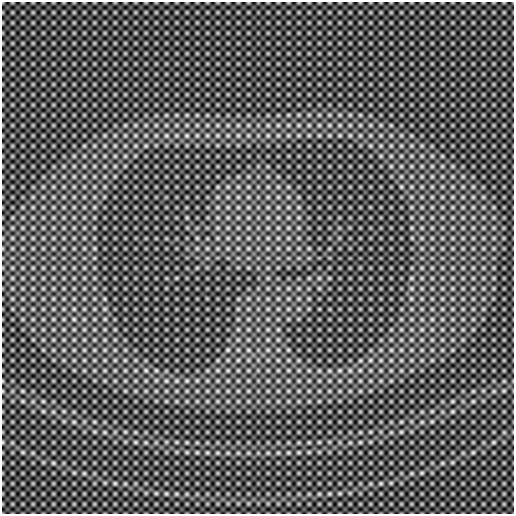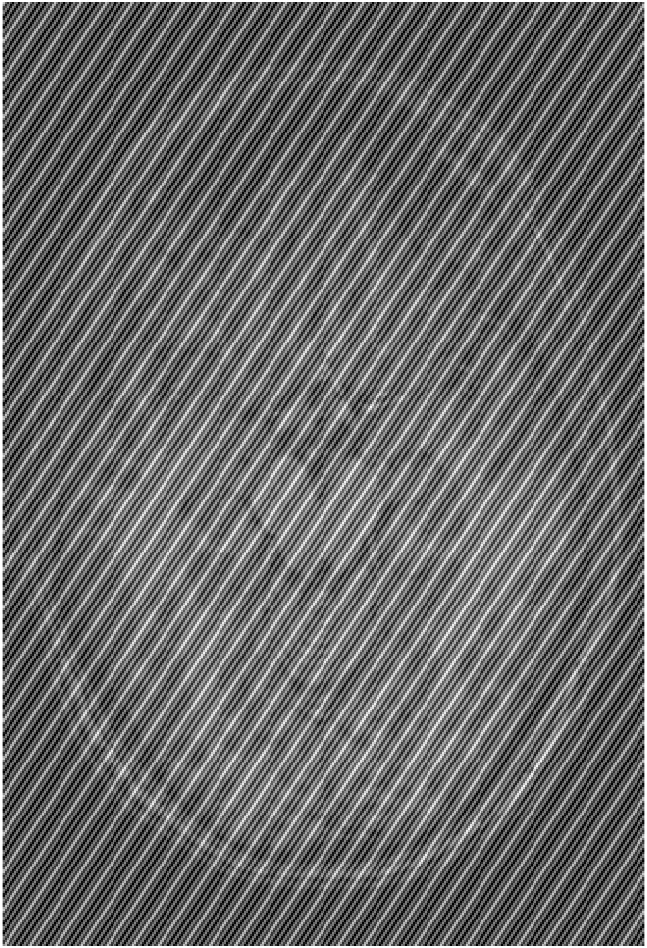

Implemente la estrategia que usted estime conveniente para poder corregir este problema y reconstruir la imagen lo mejor posible. Describa detalladamente que estrategia siguió. ***No está autorizado de usar las funciones de Matlab, ni para corregir la imagen, ni reconstruir la imagen, debe desarrollar su propio código (Usted puede hacer uso de códigos que desarrollamos en clases) ***

% Escriba su codigo acá


**c) Retroproyección (20 pts):** Usted dispone de los siguientes sinogramas, de dos imágenes desconocidas. 

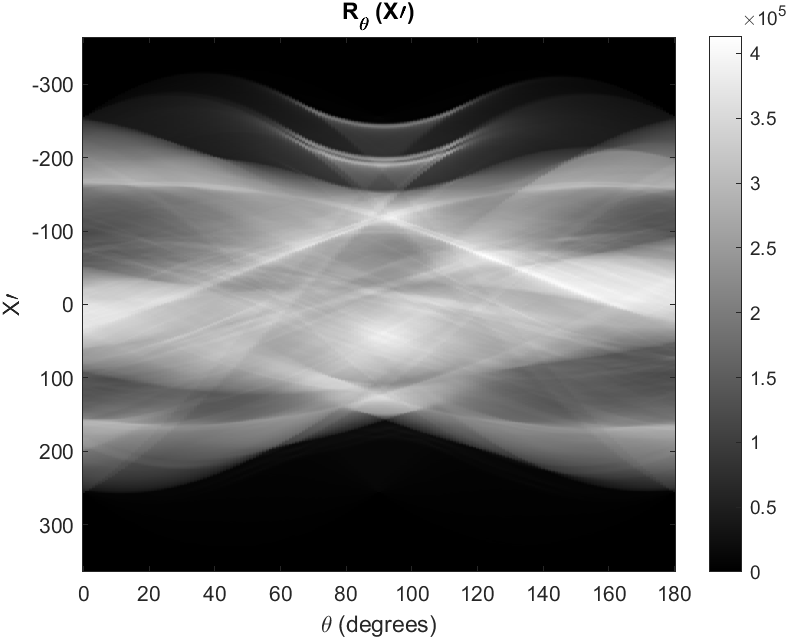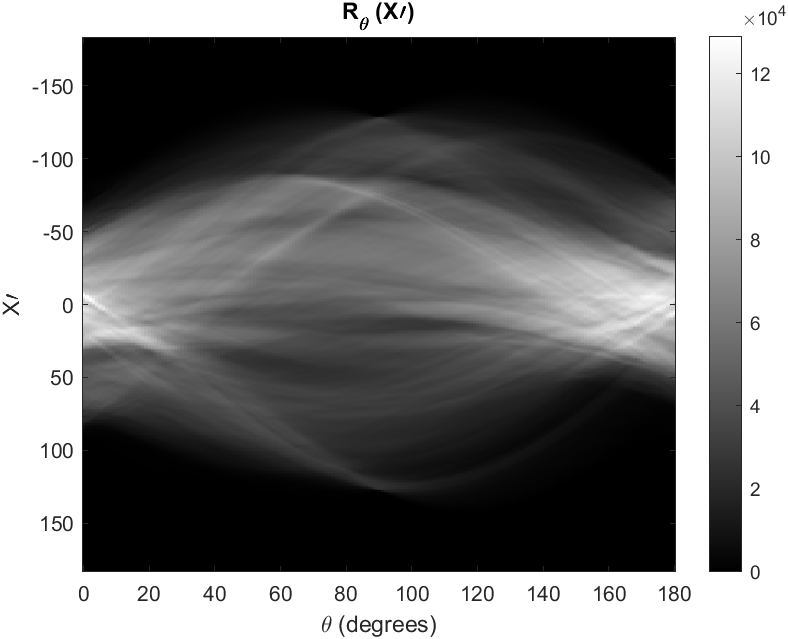

Realice la reconstrucción de la imagen original de cada uno de ellos usando retroproyección con y sin filtrar. Adicionalmente a partir de sus retroproyecciones filtradas, reconstruya la imagen resultante usando la transformada de fourier. ***No se pueden usar las funciones de la transformada de radón o iradon de Matlab, debe desarrollar su propio código. (Si esta permitido usar funciones de rotación en caso de necesitar y las funciones de la transformada de Fourier para filtrar las señales que se usaran posteriormente en cada retroproyección).***

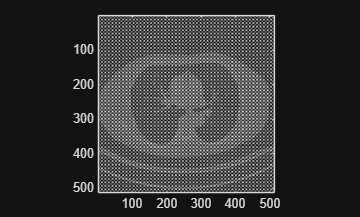

%Escriba su Código aca
%Im1:
IM1 = load('C:\Users\nncc2\OneDrive\Documentos\Tareas PRIM\Tarea 1 PRIM\IMAGENES_TAREA1\DATOS_TAREA1_PREGUNTA_B\im1.mat');
figure;
imagesc(IM1.im1);
colormap gray;
axis image;


**d) Reconstrucción de imágenes paralelas:** A partir de la imagen de cerebro *m.mat *y las sensibilidades de las bobinas entregadas en *C.mat*, genere la imagen obtenida por cada bobina y realice lo siguiente:

**d.1) (5 pts)** Reconstruya la imagen a partir de las múltiples bobinas, utilizando la ecuación de suma de cuadrados.  


$$m\left(r\right)=\sqrt{\sum_{i=1}^{N_c } |m_i \left(r\right)|^2 }$$


%Escriba su Código aca

**d.2) (5 pts) **Reconstruya la imagen a partir de las múltiples bobinas, utilizando la ecuación de combinación de sensibilidad pesadas. 


$$m\left(r\right)=\frac{\sum_{i=1}^{N_c } c_i^* \left(r\right)m_{i\left(r\right)} }{\sqrt{\sum_{i=1}^{N_c } |c_i \left(r\right)|^2 }}$$


%Escriba su Código aca

**d.3) (10 pts)** Aplique el método de reconstrucción SENSE de imágenes paralelas visto en el código de ejemplo de Matlab para un submuestreo x4, x6, x8. Muestre en pantalla las imágenes de cada una de las bobinas sub-muestreadas y también entregue la imagen reconstruida final. Comente acerca de los resultados obtenidos. 

%Escriba su Código aca


**d.4) (20 pts) **Finalmente investigue acerca del método de reconstrucción GRAPPA (Generalized autocalibrating partially parallel acquisitions), e impleméntelo a cada una de las imágenes de las bobinas con submuestreo x2, y reconstruya la imagen resultante con la ecuación de combinación de sensibilidad pesadas. Puede mirar el paper original de GRAPPA, para orientarse ([https://doi.org/10.1002/mrm.10171](https://doi.org/10.1002/mrm.10171)). 

%Escriba su Código aca